imgs_3 = img_load("data/extracted_images/3");
imgs_4 = img_load("data/extracted_images/4");
imgs = [imgs_3; imgs_4];

labels = [repmat("3", 1, length(imgs_3)) repmat("4", 1, length(imgs_4))]; % WARNING: Very advanced algorithm. Move over Google.

model = train_model(imgs, labels, 64);

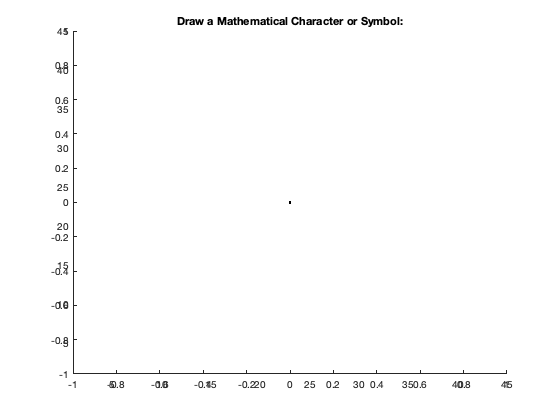

% This doesn't actually work in a live script, but run the rest of the live
% script to prep the model then run this in the Command Window.
run_draw(model)

## Vestigial — Doesn't Work, Don't Run

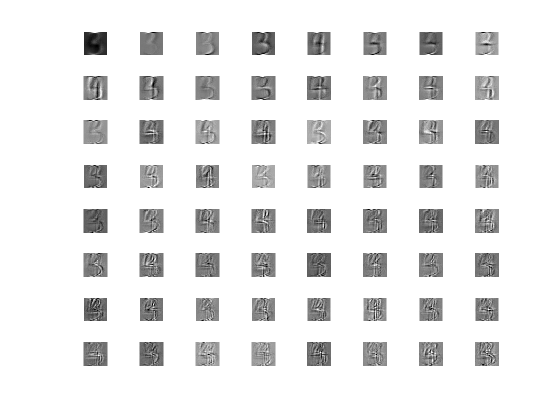

clf
subplot_size = ceil(sqrt(size(V, 2)));
for i = 1:size(V, 2)
    subplot(subplot_size, subplot_size, i);
    img_size = sqrt(size(V, 1));
    imagesc(reshape(V(:, i), [img_size img_size])); colormap('gray');
    axis equal;
    set(gca, 'visible', 'off');
end

test_data = [img_load("test-data/3"); img_load("test-data/4");];
test_data = test_data - mean(mean(imgs));

train_data_projected = V'*imgs';
test_data_projected = V'*test_data';
rets = knnsearch(train_data_projected', test_data_projected')

rets =          545
         294
         294
       12391


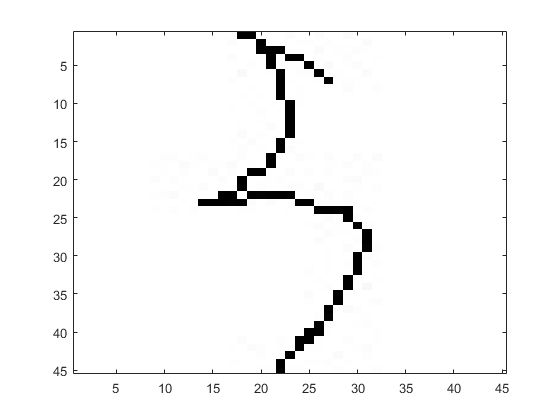

   0



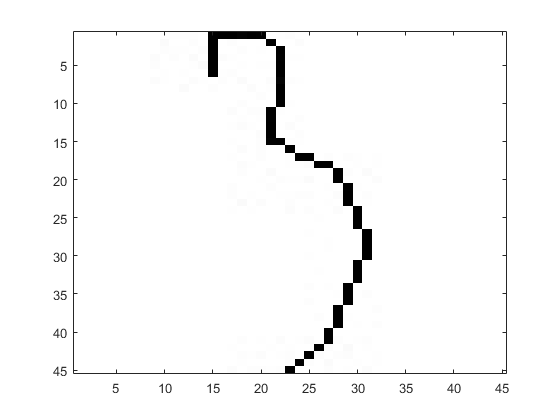

   0



   0



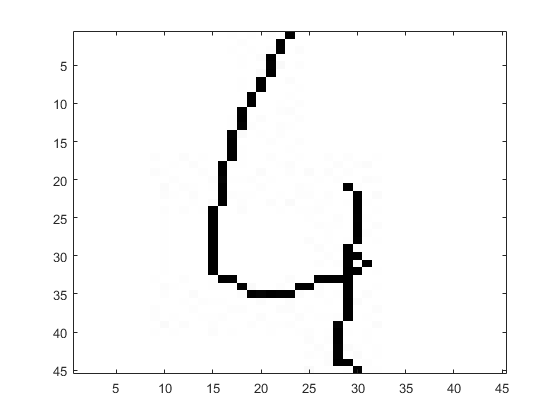

   1



for i=1:length(rets)
    figure;
    img = imgs(rets(i), :);
    img_size = sqrt(length(img));
    img = reshape(img, [img_size img_size]);
    imagesc(img); colormap('gray');
    disp(rets(i) > length(imgs_3)); % determine if 4
end